# **Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

**Nombre: Patricia Cuesta Ruiz y Laura Mambrilla Moreno**

**Fecha: 22/11/2021**

clc;
clear all;
close all;

# Tema 4. Ejercicio 2 - Identificación de objetos circulares

1) Lee la imagen

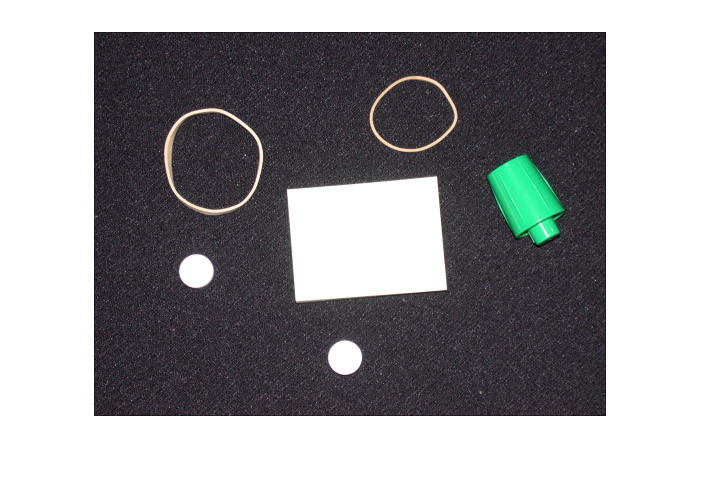

RGB = imread('pillsetc.png');
imshow(RGB);

2) Umbraliza la imagen

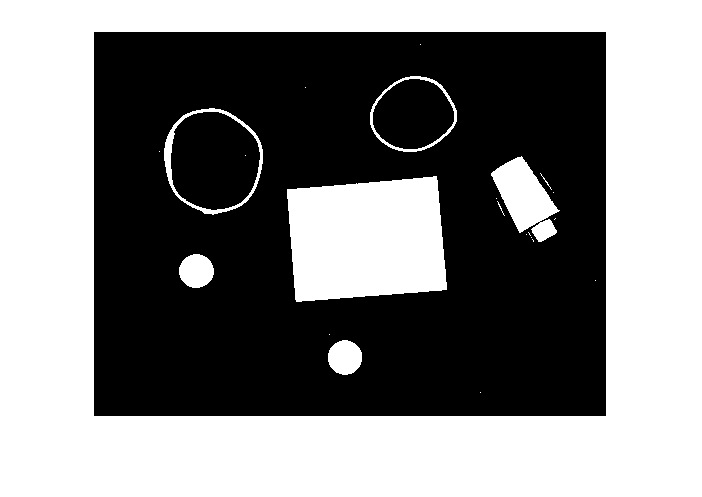

I = rgb2gray(RGB);
bw = imbinarize(I);
imshow(bw)

3) Elimina el ruido

Usando operaciones morfológicas se eliminan los píxeles que no pertenecen a los objetos de interés.

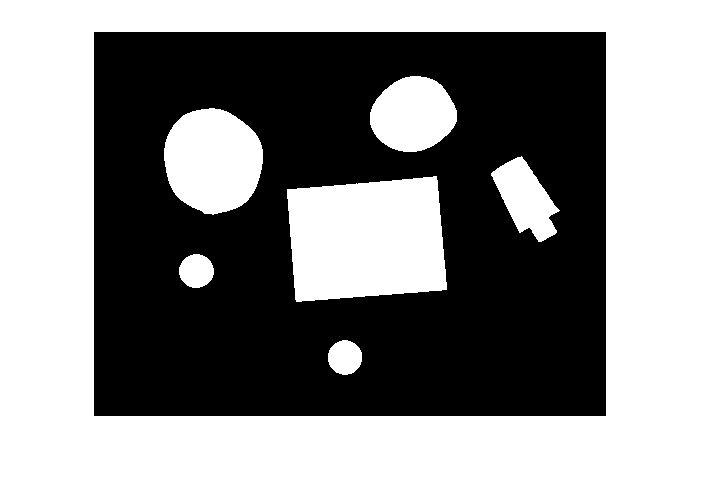

% remove all object containing fewer than 30 pixels
bw = bwareaopen(bw,30);

% fill a gap in the pen's cap
se = strel('disk',2);
bw = imclose(bw,se);

% fill any holes, so that regionprops can be used to estimate
% the area enclosed by each of the boundaries
bw = imfill(bw,'holes');

imshow(bw)

4) Encuentra los contornos

Nos centramos sólo en los límites exteriores. La opción `'noholes' `acelerará el proceso al evitar que la función `bwboundaries` busque contornos internos. 

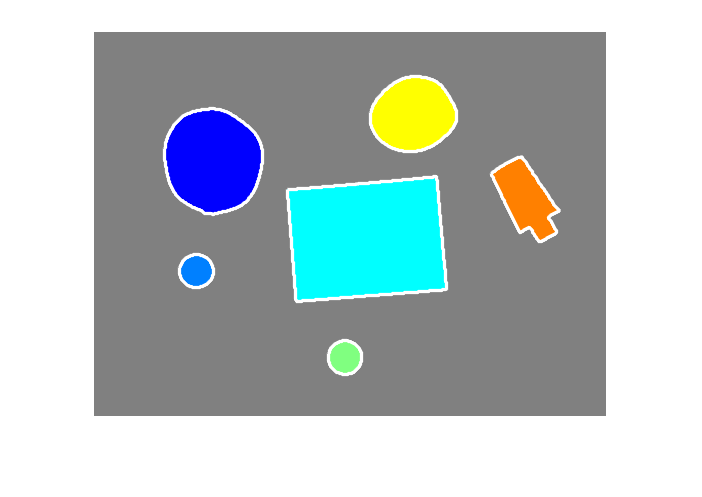

[B,L,n,A] = bwboundaries(bw,'noholes'); % Returns B, a cell array of boundary pixel locations, and matrix L where objects and holes are labeled..

% Display the label matrix
imshow(label2rgb(L, @jet, [.5 .5 .5]))

hold on  % to draw the next in the same figure

% draws the boundaries of each object.
for k = 1:n
    boundary = B{k};
    plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', 2)
end

Se pide:

- Utilice la ayuda de Matlab para conseguir información sobre la función `regionprops `(parámetros requeridos, propiedades que calcula, etc.)`.`

help regionprops

regionprops - Measure properties of image regions

    This MATLAB function returns measurements for the set of properties for each
    8-connected component (object) in the binary image, BW.

    stats = regionprops(BW,properties)
    stats = regionprops(CC,properties)
    stats = regionprops(L,properties)
    stats = regionprops(___,I,properties)
    stats = regionprops(output,___)

    See also <a href="https://www.mathworks.com/help/releases/R2020a/images/ref/bwconncomp.html">bwconncomp</a>, <a href="https://www.mathworks.com/help/releases/R2020a/images/ref/bwferet.html">bwferet</a>, <a href="https://www.mathworks.com/help/releases/R2020a/images/ref/bwpropfilt.html">bwpropfilt</a>, <a href="https://www.mathworks.com/help/releases/R2020a/images/ref/labelmatrix.html">labelmatrix</a>, <a href="https://www.mathworks.com/help/releases/R2020a/images/ref/regionprops3.html">regionprops3</a>, 
        <a href="https://www.mathworks.com/help/releases/R2020a/images/ref/watershed.html">watersh

**La función *****regionprops***** mide las propiedades de las regiones de una imagen.**

**Los argumentos de entrada pueden ser:**

- **BW = imagen binaria **

- **CC = componentes conectados**

- **L = matriz de etiquetas**

- **properties = tipo de medida ('Area', 'BoundingBox', 'FilledImage', etc.)**

- **I = imagen a medir**

- **output = tipo de valor devuelto**

**Puede ser usado:**

- `stats = regionprops(BW, properties)`**: devuelve medidas para el conjunto de propiedades especificado. **

- `stats = regionprops(CC, properties)`**: mide un conjunto de propiedades para cada componente conectado.**

- `stats = regionprops(L, properties)`**: mide un conjunto de propiedades para cada región etiquetada en la matriz de etiquetas.**

- `stats = regionprops(___, I, properties)`**: devuelve medidas para el conjunto de propiedades especificado por para cada región etiquetada en la imagen.**

- `stats = regionprops(output, ___)`**: devuelve medidas para un conjunto de propiedades, donde especifica el tipo de valor devuelto.**

         2. Usando dicha función, calcule el área, el perímetro y la circularidad de cada objeto de la imagen previa. 

stats = regionprops(bw, 'Area', 'Perimeter', 'Circularity')

stats = 6×1 struct array with fields:
    Area
    Circularity
    Perimeter


**Como observamos en la columna de circularity, hay objetos que tienen este valor inferior a 1; son los que no son circulares. **

         3. Umbralizando el valor de la circularidad, resalte los objetos que sean aproximadamente circulares (p.ej., pintando las boundaries de color diferente). Puede utilizar un slidebar para verificar la influencia del valor del umbral en el conjunto de objetos resaltados.

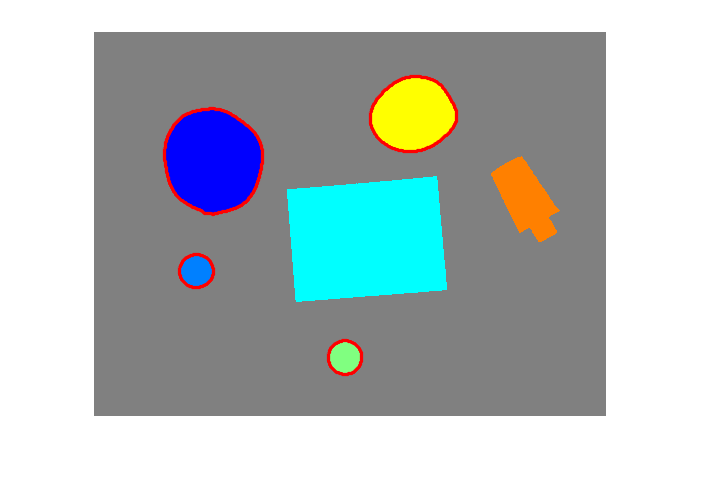

figure;
imshow(label2rgb(L, @jet, [.5 .5 .5]))
hold on
for i = 1:n
    if (stats(i).Circularity > 0.85)
        boundary = B{i};
        plot(boundary(:,2), boundary(:,1), 'r', 'LineWidth', 2)
    end 
end

         4. Cargue la imagen` 'google.jpg'``,` rellene los agujeros internos de las letras con la función imfill(bw,'holes') y determine, calculando a partir de parámetros obtenidos con la función `regionprops`, si los objetos son cóncavos o convexos. Resalte con diferente color los objetos cóncavos y los convexos, utilizando el borde del objeto convexo ('ConvexHull'). Nota: En esta pregunta hay que tener en cuenta que el primer plano es oscuro y el fondo claro, por lo que hay que modificar los pasos 2 y 3 para obtener un etiquetado correcto. 

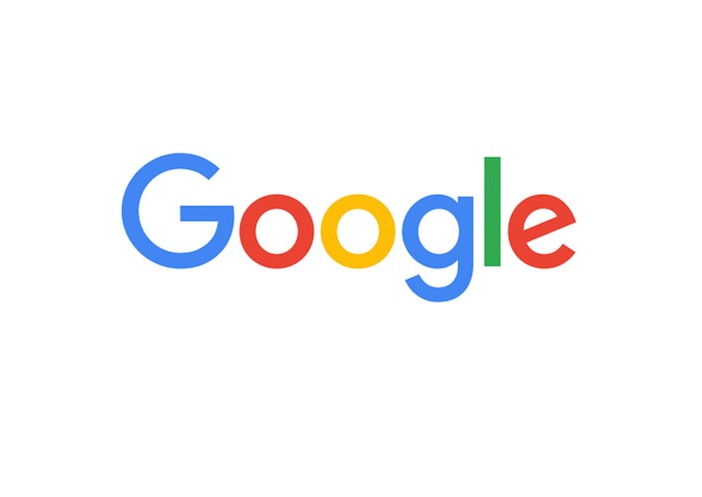

RGB1 = imread('google.jpg');

figure;
imshow(RGB1);

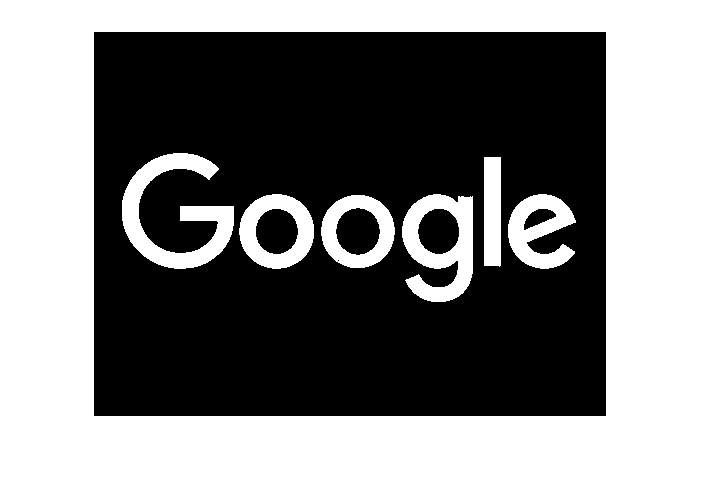

J = rgb2gray(RGB1);
J_bw = imcomplement(imbinarize(J));

figure;
imshow(J_bw);

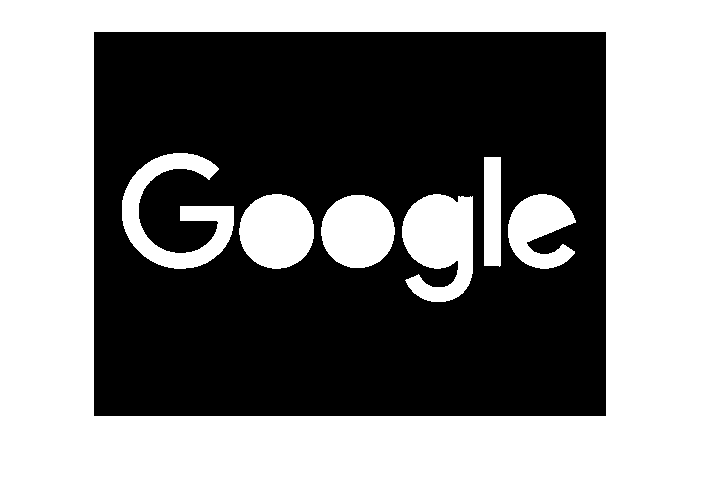

J_fill = imfill(J_bw, 'holes');

figure;
imshow(J_fill)

stats = regionprops(J_fill, 'Area', 'ConvexArea', 'ConvexHull')

stats = 6×1 struct array with fields:
    Area
    ConvexHull
    ConvexArea


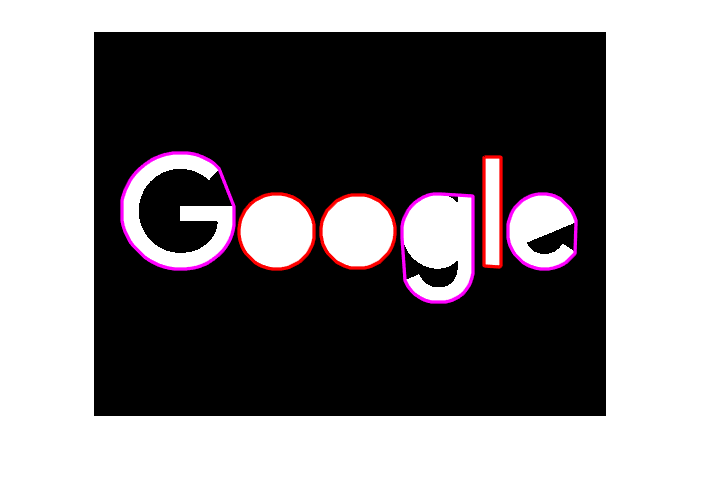

figure;
imshow(J_fill);
hold on
for j = 1:size(stats)
    if ((stats(j).Area/stats(j).ConvexArea) > 0.85) % el valor que estimamos que es óptimo para el umbral es 0.85
        boundary = stats(j).ConvexHull;
        plot(boundary(:,1), boundary(:,2), 'r', 'LineWidth', 2) % se pintan de rojo los objetos convexos
    else
        boundary = stats(j).ConvexHull;
        plot(boundary(:,1), boundary(:,2), 'm', 'LineWidth', 2) % se pintan de magenta los objetos cóncavos
    end
end

**Como se puede observar en la imagen anterior, se han resaltado de color rojo los perímetros convexos (*****ConvexHull*****) de los objetos convexos y de color magenta los de los objetos cóncavos.**

**En el siguiente código se mostraría el perímetro de las letras y su respectivo color dependiendo si es cóncavo o convexo.**

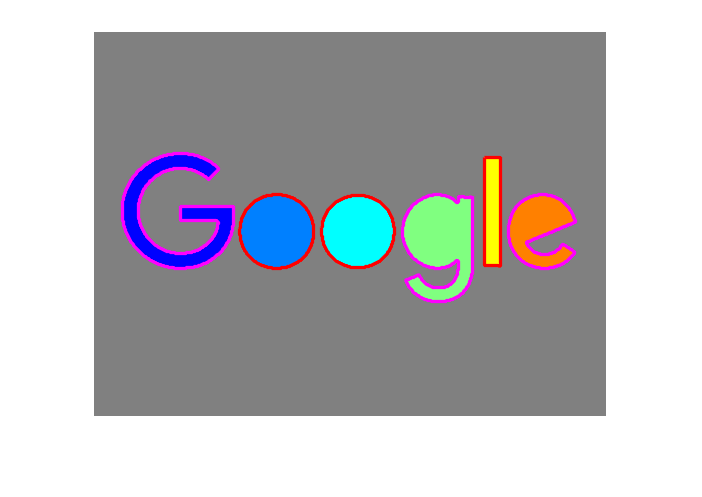

[B,L,n,A] = bwboundaries(J_fill, 'noholes');

figure;
imshow(label2rgb(L, @jet, [.5 .5 .5]))
hold on
for j = 1:n
    if ((stats(j).Area/stats(j).ConvexArea) > 0.85) % el valor que estimamos que es óptimo para el umbral es 0.85
        boundary = B{j};
        plot(boundary(:,2), boundary(:,1), 'r', 'LineWidth', 2) % se pintan de rojo los objetos convexos
    else
        boundary = B{j};
        plot(boundary(:,2), boundary(:,1), 'm', 'LineWidth', 2) % se pintan de magenta los objetos cóncavos
    end
end